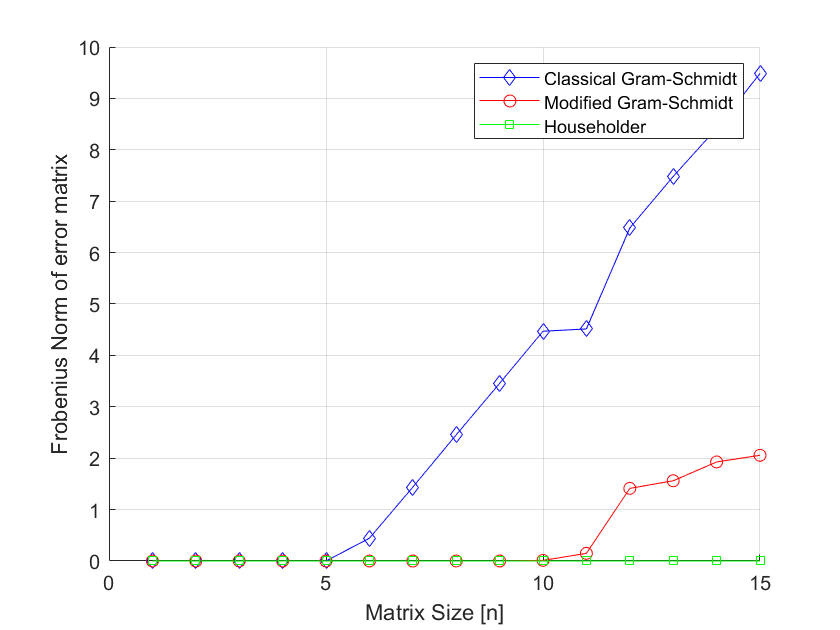

for n=2:16
a= hilb(n); % n is the size of the matrix
[q_gs,r1] = gschmidt(a); %using algorithm classical Gram--Schmidt
[q_mgs,r2] = mgschmidt(a); %using algorithm modified Gram-Schmidt
[q_hh,r3] = householder(a); % using house holder

err_gs(n-1) = norm(q_gs'*q_gs - eye(n),'fro');
err_mgs(n-1) = norm(q_mgs'*q_mgs - eye(n),'fro');
err_hh(n-1) = norm(q_hh'*q_hh - eye(n),'fro');
end 


figure(4)
hold on 
grid on 
plot(err_gs,'b-d')
plot(err_mgs,'r-o')
plot(err_hh,'g-s')
ylabel('Frobenius Norm of error matrix');
xlabel('Matrix Size [n]')
legend('Classical Gram-Schmidt','Modified Gram-Schmidt','Householder');

function [Q,R] = householder(A)
   % Write your code here.
   [m,n]=size(A);
   R=A;
   Q = eye(m);
   for j=1:n
       norm1 = norm(R(j:end,j));
       s = -sign(R(j,j));
       u1 = R(j,j)-s*norm1;
       V = R(j:end,j)/u1;
       V(1) = 1;
       t = -s*u1/norm1;      
       R(j:end,:) = R(j:end, :)-(t*V)*(V'*R(j:end,:));
       Q(:,j:end) = Q(:,j:end) - (Q(:,j:end)*V)*(t*V)';
   end
end

function [Q,R] = mgschmidt(A)
   % Write your code here.
   %this is based on the algorithm given in the tutorial
   [m,n]=size(A);
   Q=zeros(m,n);
   R=zeros(n,n);
   for i=1:n
       v(:,i)=A(:,i);
   end
   for i=1:n
       R(i,i)=norm(v(:,i));
       Q(:,i)=v(:,i)/R(i,i);
       for j=i+1:n
           R(i,j)=Q(:,i)'*v(:,j);
           v(:,j)=v(:,j)-R(i,j)*Q(:,i);
       end
   end
end

function [Q,R] = gschmidt(A)
   % Write your code here.
   % based on the algorithm introduced in tutorial 
   [m,n]=size(A);
   Q = zeros(m,n);
   R = zeros(n,n);
   for j = 1:n
       v=A(:,j);
       for i = 1:j-1
           R(i,j)=Q(:,i)'*A(:,j);
           v=v-R(i,j)*Q(:,i);
       end
       R(j,j)=norm(v);
       Q(:,j)=v/R(j,j);
   end
   end

function A = Hilbert_matrix(size)

A = zeros(size,size);

for i=1:size
    for j=1:size
        A(i,j) = 1/(i+j-1);
    end 
end 
end